
cd('/Volumes/PcSSDA/AChMut/20220422_112_AChmtut_SW_001')
ExperimentName='20220422_112_AChmtut_SW_001'; % Give a specific name to this experiment or this analysis
FirstAcq=13; % What's the acquisition number of the first offical recording
number_of_acq = 23; % How many chunks of recordings are there?
Dark_hours=[13 14 15 16 17 18 19 20 21 22 23 24 25]

Dark_hours =     13    14    15    16    17    18    19    20    21    22    23    24    25


darktime_calc = 0; % 0 or 1, determining different method to calculate dark time
animal='112 AChmut 1 ';

analysis_name=[ExperimentName,'_analysis_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 

load('FLP_analysis.mat')

figure
plot(time_z_all_dark, )

Invalid expression. When calling a function or indexing a
variable, use parentheses. Otherwise, check for mismatched
delimiters.

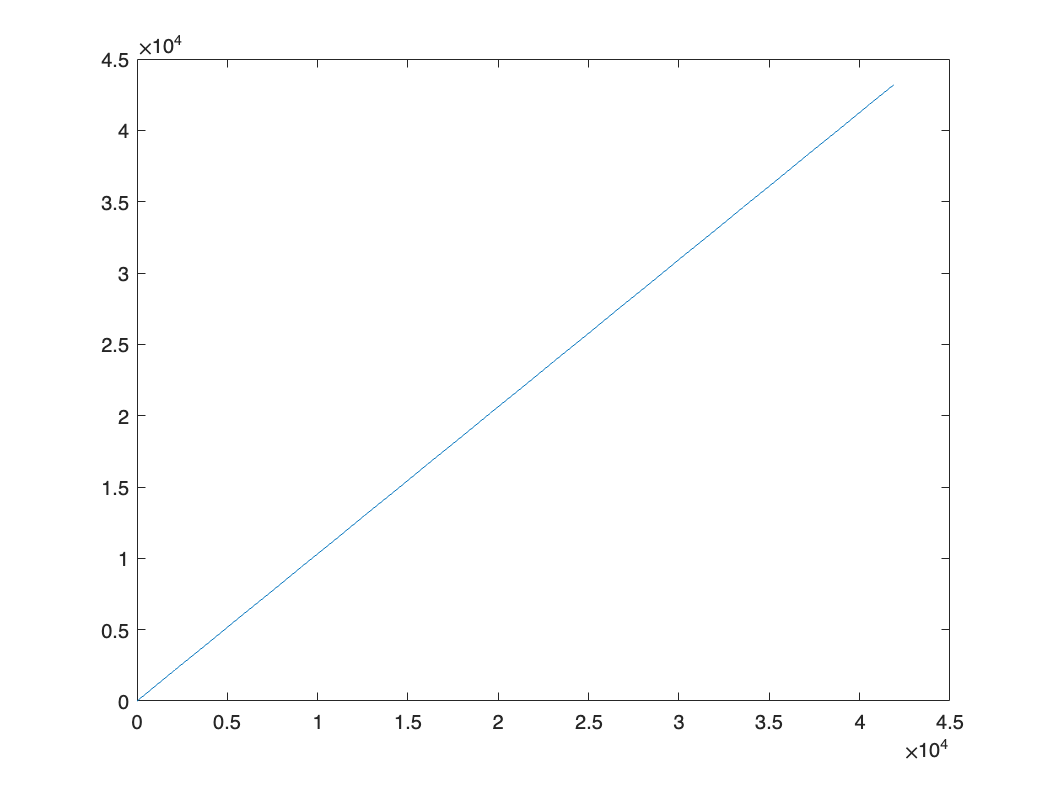

figure
plot(time_z_all_darkonly)

time_max = max(time_z_all_darkonly)

time_max = 4.3199e+04

length(time_z_all_darkonly)

ans = 41893

min(time_z_all_darkonly)

ans = 0.9310

time_pooled = (2:4:(ceil(time_max/4)*4)) + 12*900;
time_pooled = (0:1:(length(time_pooled)-1)) + 10800;
circadian_time = NaN(ceil(time_max/4),1);
% time_pooled = zeros(ceil(time_max/4),1);
tau_pooled = NaN(ceil(time_max/4),1);
states_pooled = NaN(ceil(time_max/4),1);

helper = 1;

for i = 1:ceil(time_max/4)
    index = find(time_z_all_darkonly > (i-1)*4 & time_z_all_darkonly <= i*4);
    circadian_time(i) = time_pooled(i);

    if isempty(index) == 0
        weighted_sum = sum(tau_empTrunc_all_darkonly(index).*intensity_all_darkonly (index));
        tau_pooled(i) = weighted_sum/sum(intensity_all_darkonly (index));
        states_pooled(i) = states_for_time_all_dark(index(1));
        helper = helper*0;
    elseif helper ==0
        tau_pooled(i) = tau_pooled(i-1);
        states_pooled(i) = states_pooled(i-1);
%         time_pooled(i) = NaN;

    end

end

size(tau_pooled)

ans =        10800           1


size(states_pooled)

ans =        10800           1


size(circadian_time)

ans =        10800           1


sum(isnan(tau_pooled))

ans = 0

sum(isnan(states_pooled))

ans = 0

sum(isnan(circadian_time))

ans = 0

states_pooled(find(states_pooled==2))=0;
states_pooled(find(states_pooled==3))=1;
states_pooled(find(states_pooled==4))=1;

Temperature_path='/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/'

Temperature_path = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/'

cd(Temperature_path)

rawData1 = ([Temperature_path,ExperimentName,'_0920.mat'])

rawData1 = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/20220422_112_AChmtut_SW_001_0920.mat'

OptResults1=([Temperature_path,ExperimentName,'OptResults_0920.mat'])

OptResults1 = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/20220422_112_AChmtut_SW_001OptResults_0920.mat'

save(rawData1, 'circadian_time','states_pooled','tau_pooled')

example2_Optimization(rawData1, 1, OptResults1)

iteration 1/121: PWP values of size and shift are [0.25 , -5.0].
iteration 2/121: PWP values of size and shift are [0.25 , -4.0].
iteration 3/121: PWP values of size and shift are [0.25 , -3.0].
iteration 4/121: PWP values of size and shift are [0.25 , -2.0].
iteration 5/121: PWP values of size and shift are [0.25 , -1.0].
iteration 6/121: PWP values of size and shift are [0.25 , 0.0].
iteration 7/121: PWP values of size and shift are [0.25 , 1.0].
iteration 8/121: PWP values of size and shift are [0.25 , 2.0].
iteration 9/121: PWP values of size and shift are [0.25 , 3.0].
iteration 10/121: PWP values of size and shift are [0.25 , 4.0].
iteration 11/121: PWP values of size and shift are [0.25 , 5.0].
iteration 12/121: PWP values of size and shift are [1.25 , -5.0].
iteration 13/121: PWP values of size and shift are [1.25 , -4.0].
iteration 14/121: PWP values of size and shift are [1.25 , -3.0].
iteration 15/121: PWP values of size and shift are [1.25 , -2.0].
iteration 16/121: PWP val

OptimizedParameters = struct with fields:
               sizePWP: 2.250000000000000
              shiftPWP: 0
        lowerAsymptote: 4.330415407027031
        upperAsymptote: 4.173665619114070
      wakeTimeConstant: 0.346633920569163
      nremTimeConstant: 1.291517342764402
              scalePWP: 0.097618515540848
    circadianAmplitude: 0.059112658302260
        circadianPhase: 14.202067607810886


correlation =    0.953281275738751


mean_error =    0.004822007989344


load(OptResults1)

figure
plot(simulatedT)
hold on
plot(rawT)

cd('/Volumes/PcSSDA/AChMut/20220206_112_8_AChMut_SW_001')
ExperimentName='20220206_112_8_AChMut_SW_001'; % Give a specific name to this experiment or this analysis
FirstAcq=7; % What's the acquisition number of the first offical recording
number_of_acq = 12; % How many chunks of recordings are there?
Dark_hours=[7 8 9 10 11 12 13 14 15 16 17 18]

Dark_hours =      7     8     9    10    11    12    13    14    15    16    17    18


darktime_calc = 0; % 0 or 1, determining different method to calculate dark time
animal='112 AChmut 2 ';

analysis_name=[ExperimentName,'_analysis_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 

Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


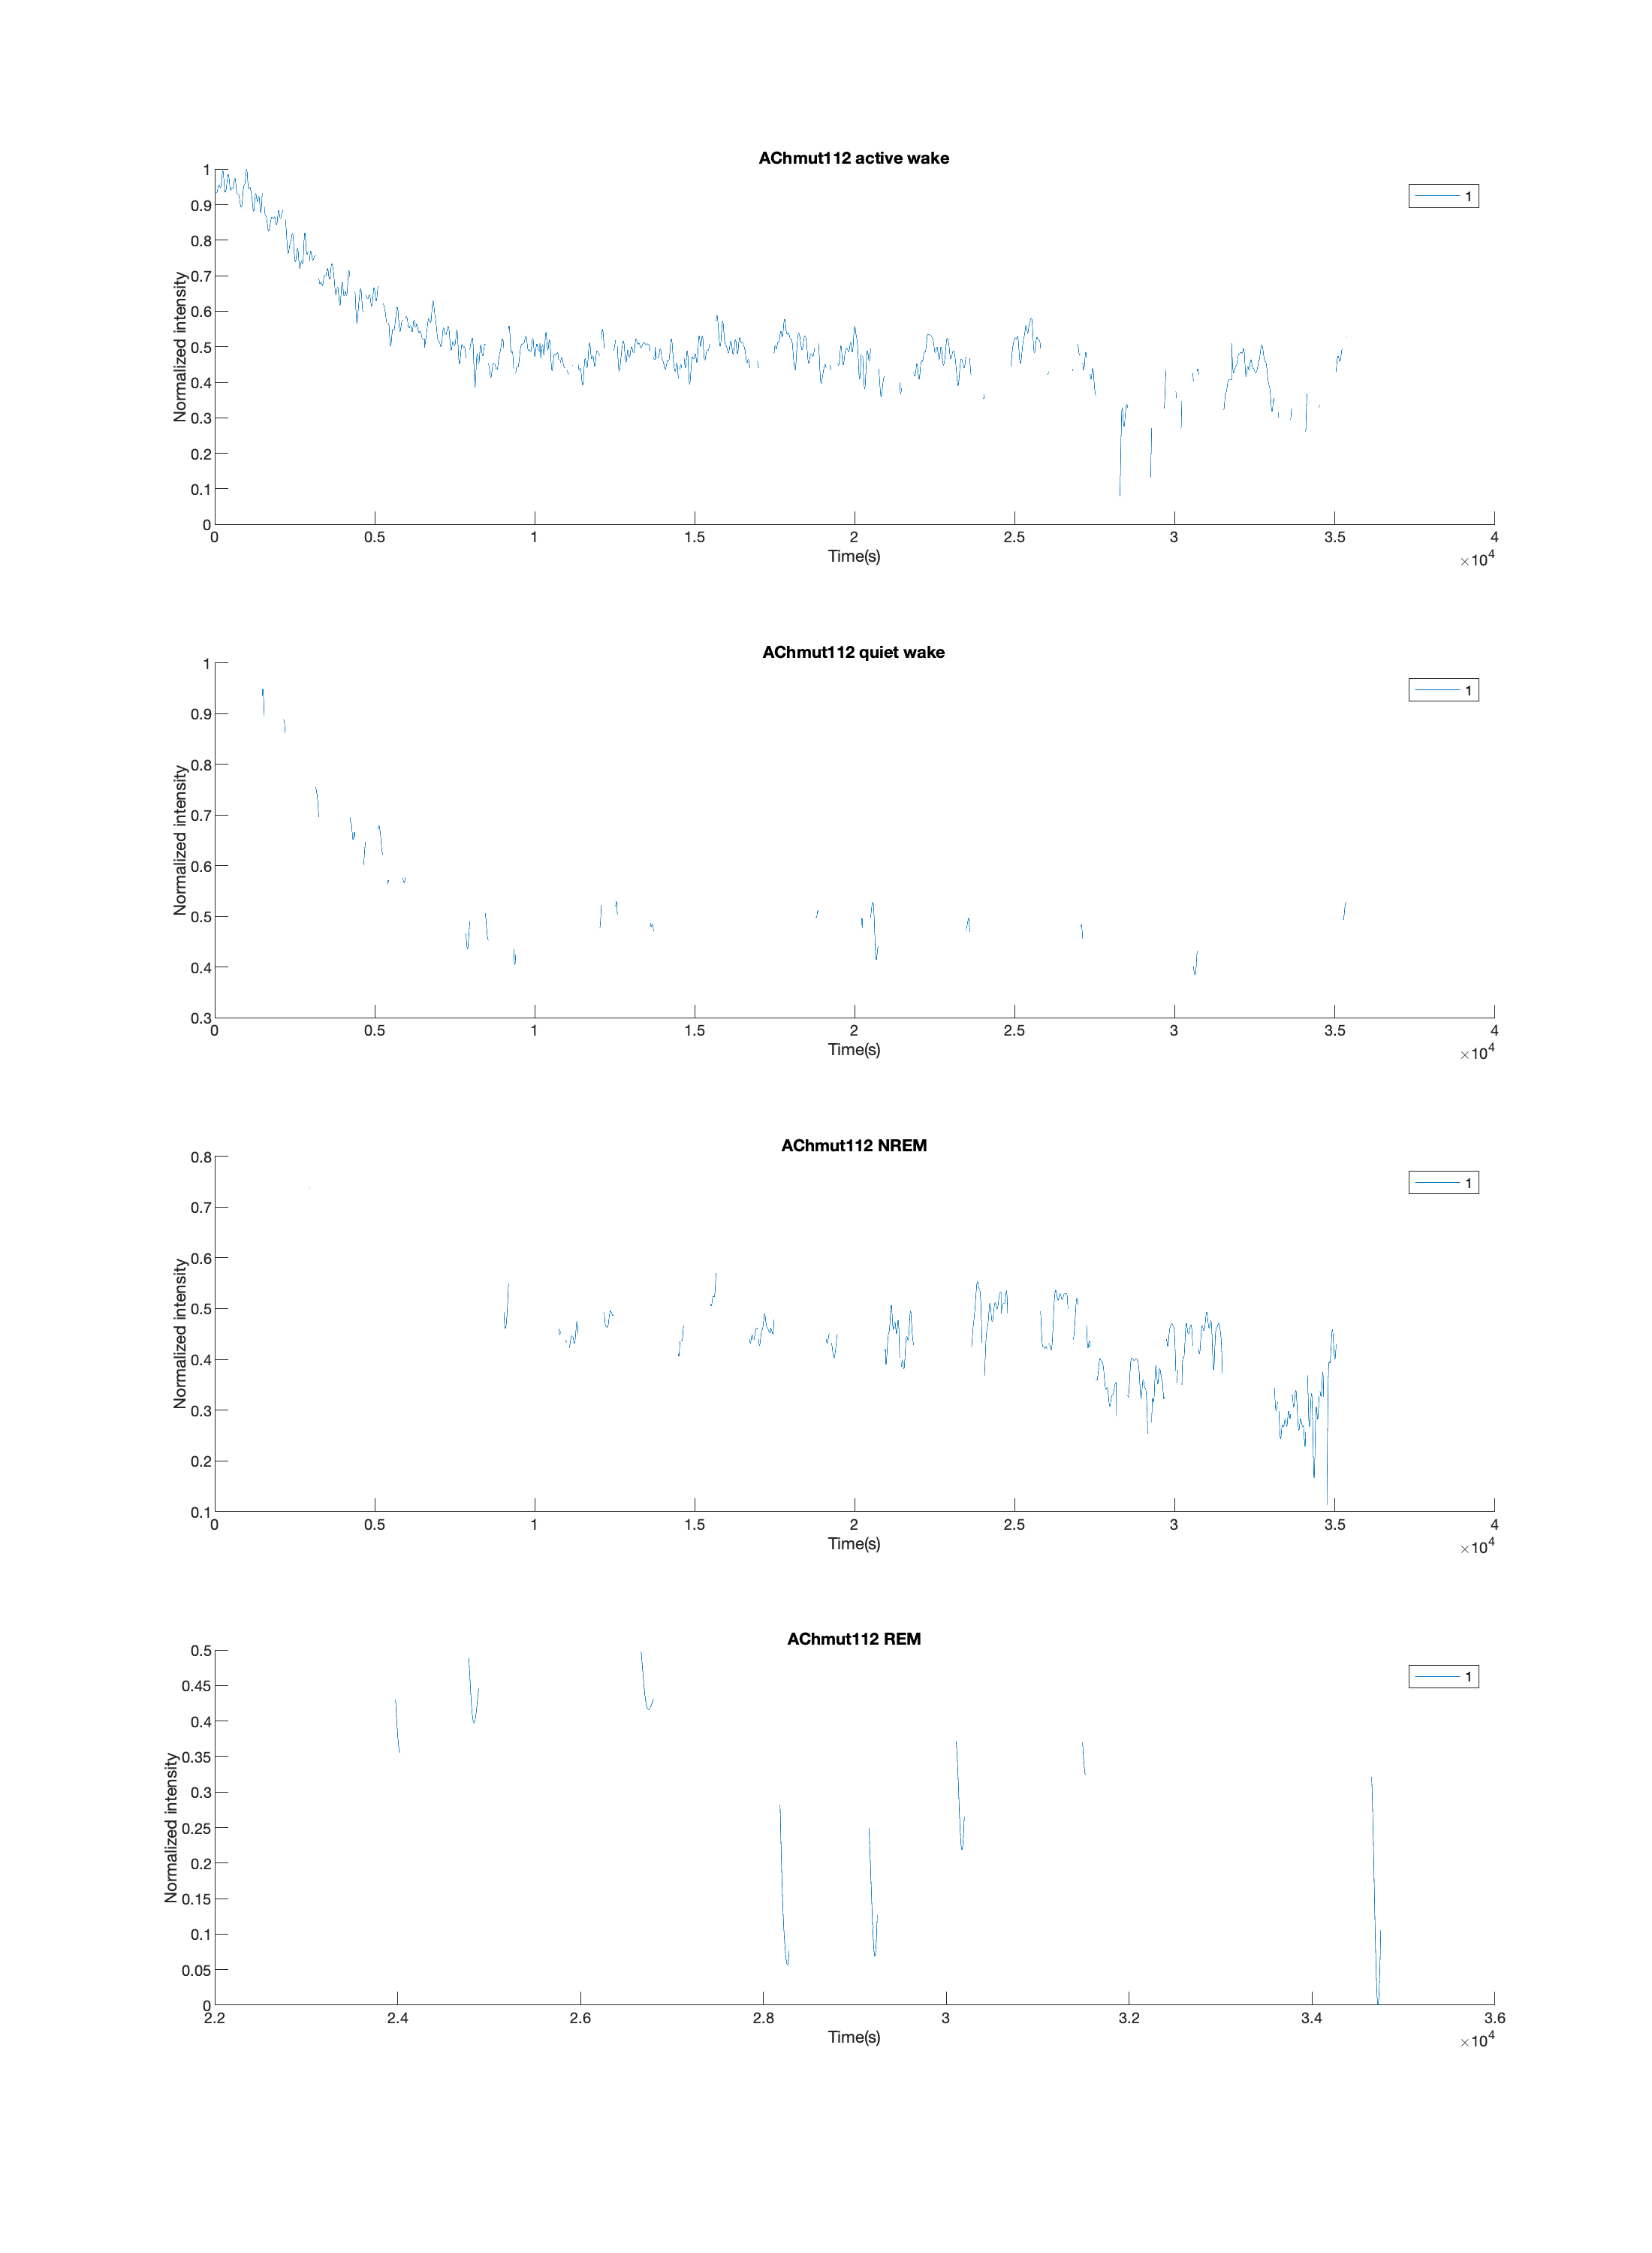

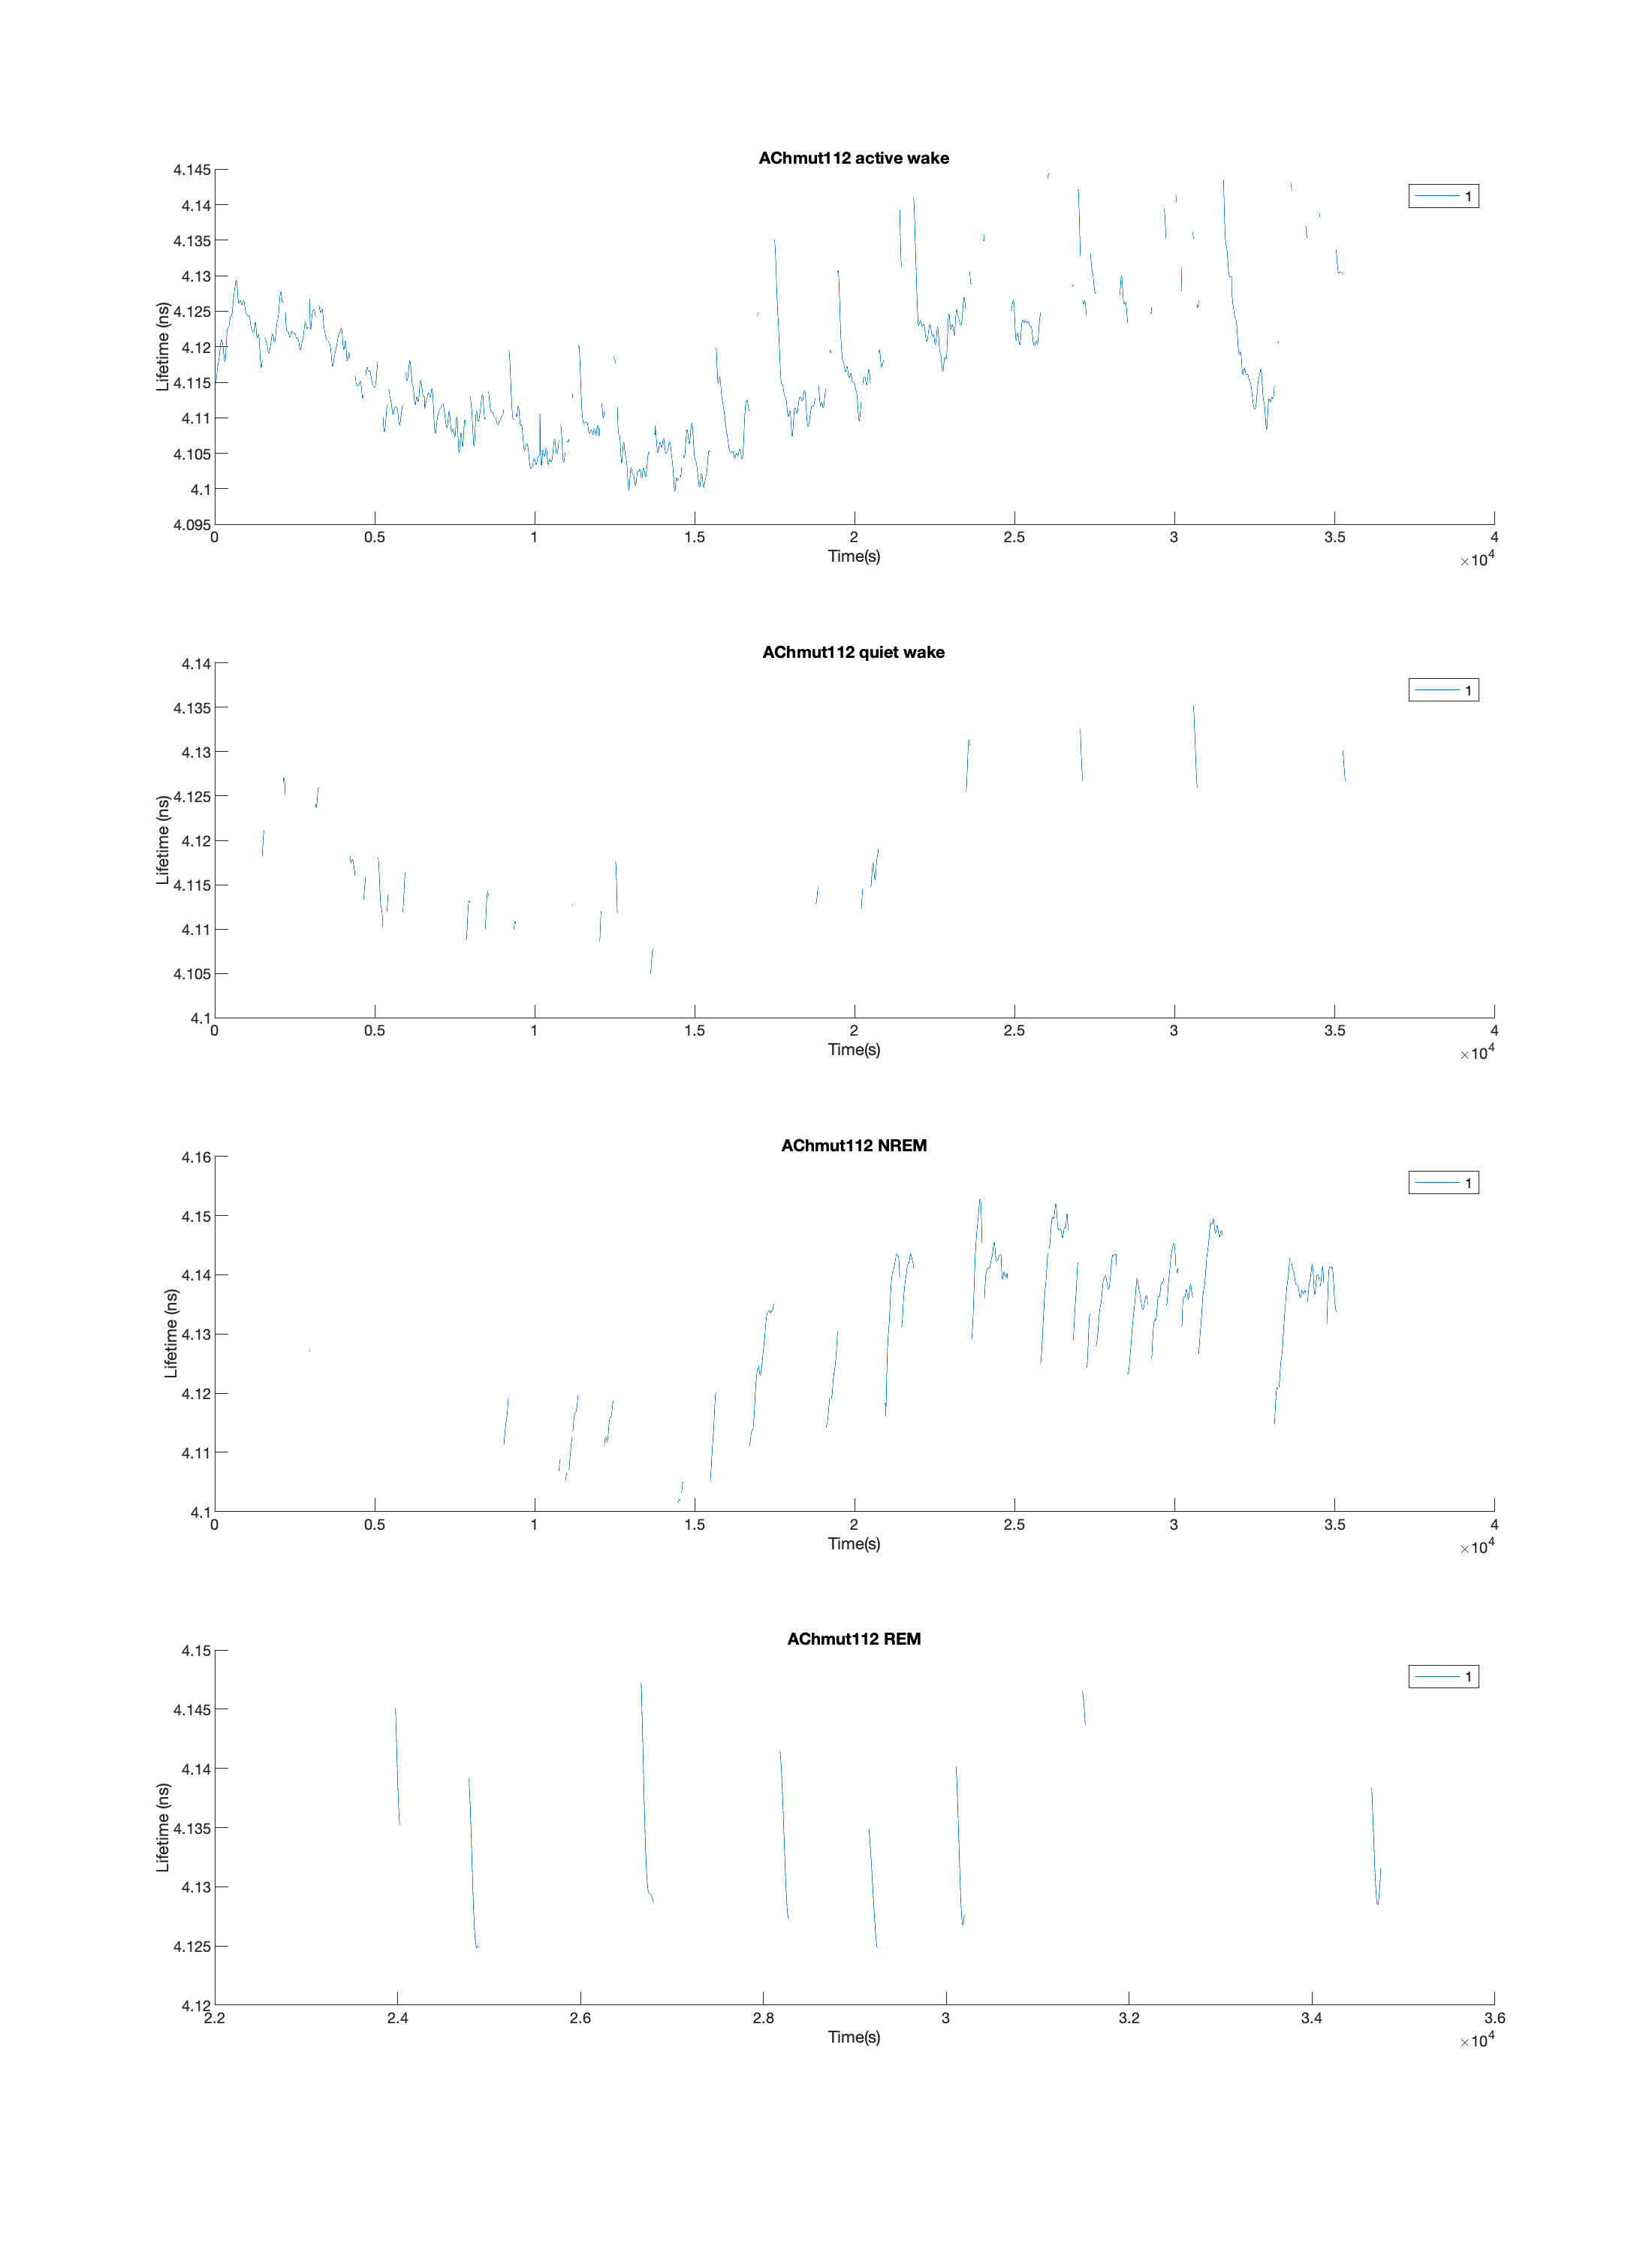

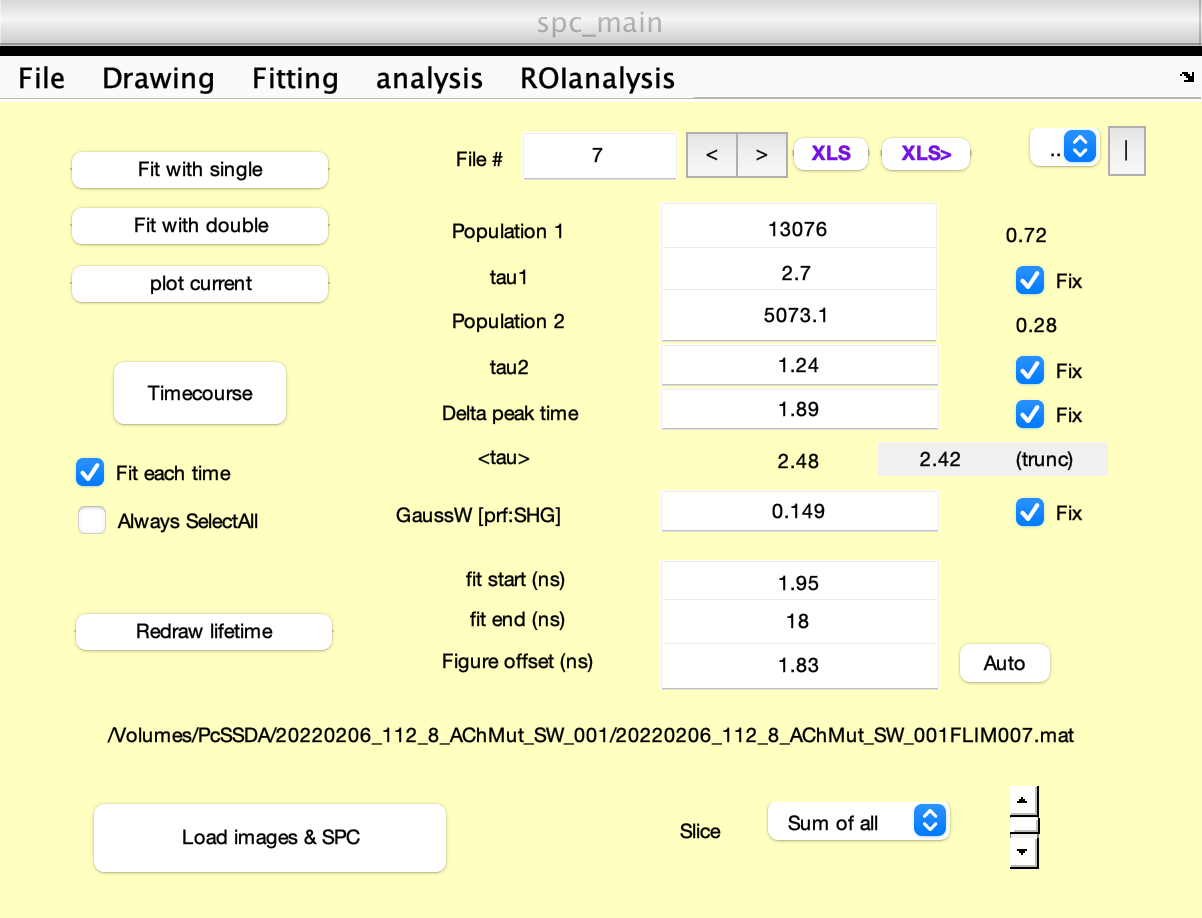

load('FLP_analysis.mat');

figure
plot(time_z_all_darkonly)

time_max = max(time_z_all_darkonly)

time_max =      4.319922000000000e+04


length(time_z_all_darkonly)

ans =        41436


min(time_z_all_darkonly)

ans =      5.027229999999981e+02


time_pooled = (2:4:(ceil(time_max/4)*4)) + 12*900;
time_pooled = (0:1:(length(time_pooled)-1)) + 10800;
circadian_time = NaN(ceil(time_max/4),1);
% time_pooled = zeros(ceil(time_max/4),1);
tau_pooled = NaN(ceil(time_max/4),1);
states_pooled = NaN(ceil(time_max/4),1);

helper = 1;

for i = 1:ceil(time_max/4)
    index = find(time_z_all_darkonly > (i-1)*4 & time_z_all_darkonly <= i*4);
    circadian_time(i) = time_pooled(i);

    if isempty(index) == 0
        weighted_sum = sum(tau_empTrunc_all_darkonly(index).*intensity_all_darkonly (index));
        tau_pooled(i) = weighted_sum/sum(intensity_all_darkonly (index));
        states_pooled(i) = states_for_time_all_dark(index(1));
        helper = helper*0;
    elseif helper ==0
        tau_pooled(i) = tau_pooled(i-1);
        states_pooled(i) = states_pooled(i-1);
%         time_pooled(i) = NaN;

    end

end

size(tau_pooled)

ans =        10800           1


size(states_pooled)

ans =        10800           1


size(circadian_time)

ans =        10800           1


sum(isnan(tau_pooled))

ans =    125


sum(isnan(states_pooled))

ans =    125


sum(isnan(circadian_time))

ans =      0


NaN_index = isnan(tau_pooled);
tau_pooled(find(NaN_index == 1)) = [];
states_pooled(find(NaN_index == 1)) = [];
circadian_time(find(NaN_index == 1)) = [];
size(tau_pooled)

ans =        10675           1


size(states_pooled)

ans =        10675           1


size(circadian_time)

ans =        10675           1


states_pooled(find(states_pooled==2))=0;
states_pooled(find(states_pooled==3))=1;
states_pooled(find(states_pooled==4))=1;

Temperature_path='/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/'

Temperature_path = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/'

cd(Temperature_path)

rawData2 = ([Temperature_path,ExperimentName,'_0920.mat'])

rawData2 = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/20220206_112_8_AChMut_SW_001_0920.mat'

OptResults2=([Temperature_path,ExperimentName,'OptResults_0920.mat'])

OptResults2 = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/20220206_112_8_AChMut_SW_001OptResults_0920.mat'

save(rawData2, 'circadian_time','states_pooled','tau_pooled')

example2_Optimization(rawData2, 1, OptResults2)

iteration 1/121: PWP values of size and shift are [0.25 , -5.0].
iteration 2/121: PWP values of size and shift are [0.25 , -4.0].
iteration 3/121: PWP values of size and shift are [0.25 , -3.0].
iteration 4/121: PWP values of size and shift are [0.25 , -2.0].
iteration 5/121: PWP values of size and shift are [0.25 , -1.0].
iteration 6/121: PWP values of size and shift are [0.25 , 0.0].
iteration 7/121: PWP values of size and shift are [0.25 , 1.0].
iteration 8/121: PWP values of size and shift are [0.25 , 2.0].
iteration 9/121: PWP values of size and shift are [0.25 , 3.0].
iteration 10/121: PWP values of size and shift are [0.25 , 4.0].
iteration 11/121: PWP values of size and shift are [0.25 , 5.0].
iteration 12/121: PWP values of size and shift are [1.25 , -5.0].
iteration 13/121: PWP values of size and shift are [1.25 , -4.0].
iteration 14/121: PWP values of size and shift are [1.25 , -3.0].
iteration 15/121: PWP values of size and shift are [1.25 , -2.0].
iteration 16/121: PWP val

OptimizedParameters = struct with fields:
               sizePWP: 4.250000000000000
              shiftPWP: 0
        lowerAsymptote: 4.126174792161315
        upperAsymptote: 4.058676318726476
      wakeTimeConstant: 0.332072167768014
      nremTimeConstant: 0.179603969063103
              scalePWP: 0.089639379155691
    circadianAmplitude: 0.087959065896092
        circadianPhase: -3.151831093723587


correlation =    0.961514647747494


mean_error =    0.005113305333568


load(OptResults2)

figure
plot(simulatedT)
hold on
plot(rawT)

cd('/Volumes/PcSSDA/AChMut/20220425_109_AChmut_SW_001')
ExperimentName='20220425_109_AChmut_SW_001'; % Give a specific name to this experiment or this analysis
FirstAcq=11; % What's the acquisition number of the first offical recording
number_of_acq = 24; % How many chunks of recordings are there?
Dark_hours=[12 13 14 15 16 17 18 19 20 21 22 23]

Dark_hours =     12    13    14    15    16    17    18    19    20    21    22    23


darktime_calc = 0; % 0 or 1, determining different method to calculate dark time
animal='109 AChmut 1 ';

analysis_name=[ExperimentName,'_analysis_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 

Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


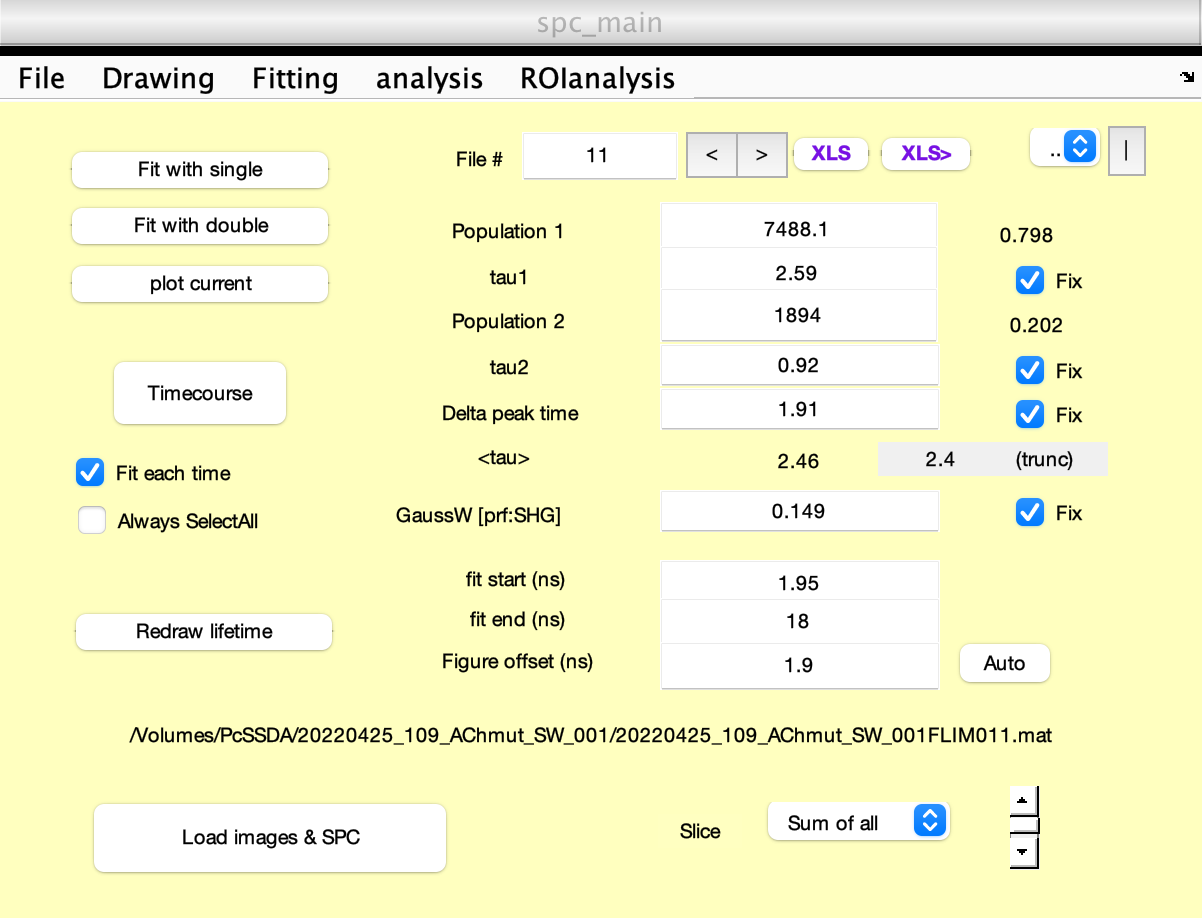

load('FLP_analysis.mat');

figure
plot(time_z_all_darkonly)

time_max = max(time_z_all_darkonly)

time_max =        42533


length(time_z_all_darkonly)

ans =        41268


min(time_z_all_darkonly)

ans =    0.880000000004657


time_pooled = (2:4:(ceil(time_max/4)*4)) + 12*900;
time_pooled = (0:1:(length(time_pooled)-1)) + 10800;
circadian_time = NaN(ceil(time_max/4),1);
% time_pooled = zeros(ceil(time_max/4),1);
tau_pooled = NaN(ceil(time_max/4),1);
states_pooled = NaN(ceil(time_max/4),1);

helper = 1;

for i = 1:ceil(time_max/4)
    index = find(time_z_all_darkonly > (i-1)*4 & time_z_all_darkonly <= i*4);
    circadian_time(i) = time_pooled(i);

    if isempty(index) == 0
        weighted_sum = sum(tau_empTrunc_all_darkonly(index).*intensity_all_darkonly (index));
        tau_pooled(i) = weighted_sum/sum(intensity_all_darkonly (index));
        states_pooled(i) = states_for_time_all_dark(index(1));
        helper = helper*0;
    elseif helper ==0
        tau_pooled(i) = tau_pooled(i-1);
        states_pooled(i) = states_pooled(i-1);
%         time_pooled(i) = NaN;

    end

end

size(tau_pooled)

ans =        10634           1


size(states_pooled)

ans =        10634           1


size(circadian_time)

ans =        10634           1


sum(isnan(tau_pooled))

ans =      0


sum(isnan(states_pooled))

ans =      0


sum(isnan(circadian_time))

ans =      0


NaN_index = isnan(tau_pooled);
tau_pooled(find(NaN_index == 1)) = [];
states_pooled(find(NaN_index == 1)) = [];
circadian_time(find(NaN_index == 1)) = [];
size(tau_pooled)

ans =        10634           1


size(states_pooled)

ans =        10634           1


size(circadian_time)

ans =        10634           1


states_pooled(find(states_pooled==2))=0;
states_pooled(find(states_pooled==3))=1;
states_pooled(find(states_pooled==4))=1;

Temperature_path='/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/'

Temperature_path = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/'

cd(Temperature_path)

rawData3 = ([Temperature_path,ExperimentName,'_0920.mat'])

rawData3 = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/20220425_109_AChmut_SW_001_0920.mat'

OptResults3=([Temperature_path,ExperimentName,'OptResults_0920.mat'])

OptResults3 = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/20220425_109_AChmut_SW_001OptResults_0920.mat'

save(rawData3, 'circadian_time','states_pooled','tau_pooled')

example2_Optimization(rawData3, 1, OptResults3)

iteration 1/121: PWP values of size and shift are [0.25 , -5.0].
iteration 2/121: PWP values of size and shift are [0.25 , -4.0].
iteration 3/121: PWP values of size and shift are [0.25 , -3.0].
iteration 4/121: PWP values of size and shift are [0.25 , -2.0].
iteration 5/121: PWP values of size and shift are [0.25 , -1.0].
iteration 6/121: PWP values of size and shift are [0.25 , 0.0].
iteration 7/121: PWP values of size and shift are [0.25 , 1.0].
iteration 8/121: PWP values of size and shift are [0.25 , 2.0].
iteration 9/121: PWP values of size and shift are [0.25 , 3.0].
iteration 10/121: PWP values of size and shift are [0.25 , 4.0].
iteration 11/121: PWP values of size and shift are [0.25 , 5.0].
iteration 12/121: PWP values of size and shift are [1.25 , -5.0].
iteration 13/121: PWP values of size and shift are [1.25 , -4.0].
iteration 14/121: PWP values of size and shift are [1.25 , -3.0].
iteration 15/121: PWP values of size and shift are [1.25 , -2.0].
iteration 16/121: PWP val

OptimizedParameters = struct with fields:
               sizePWP: 2.250000000000000
              shiftPWP: -5
        lowerAsymptote: 4.141112731110955
        upperAsymptote: 4.116692850899555
      wakeTimeConstant: 0.128071874983828
      nremTimeConstant: 0.032840313984633
              scalePWP: -0.018216203996194
    circadianAmplitude: 0.018084346430813
        circadianPhase: -1.833877316349552


correlation =    0.883772764316924


mean_error =    0.005450112343731


load(OptResults3)

figure
plot(simulatedT)
hold on
plot(rawT)

cd('/Volumes/PcSSDA/AChMut/20220207_109_AChMut_SW_001')
ExperimentName='20220207_109_AChMut_SW_001'; % Give a specific name to this experiment or this analysis
FirstAcq=10; % What's the acquisition number of the first offical recording
number_of_acq = 10; % How many chunks of recordings are there?
Dark_hours=[10 11 12 13 14 15 16 17 18 19 20 21 22]

Dark_hours =     10    11    12    13    14    15    16    17    18    19    20    21    22


darktime_calc = 0; % 0 or 1, determining different method to calculate dark time
animal='109 AChmut 2 ';

analysis_name=[ExperimentName,'_analysis_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 

Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


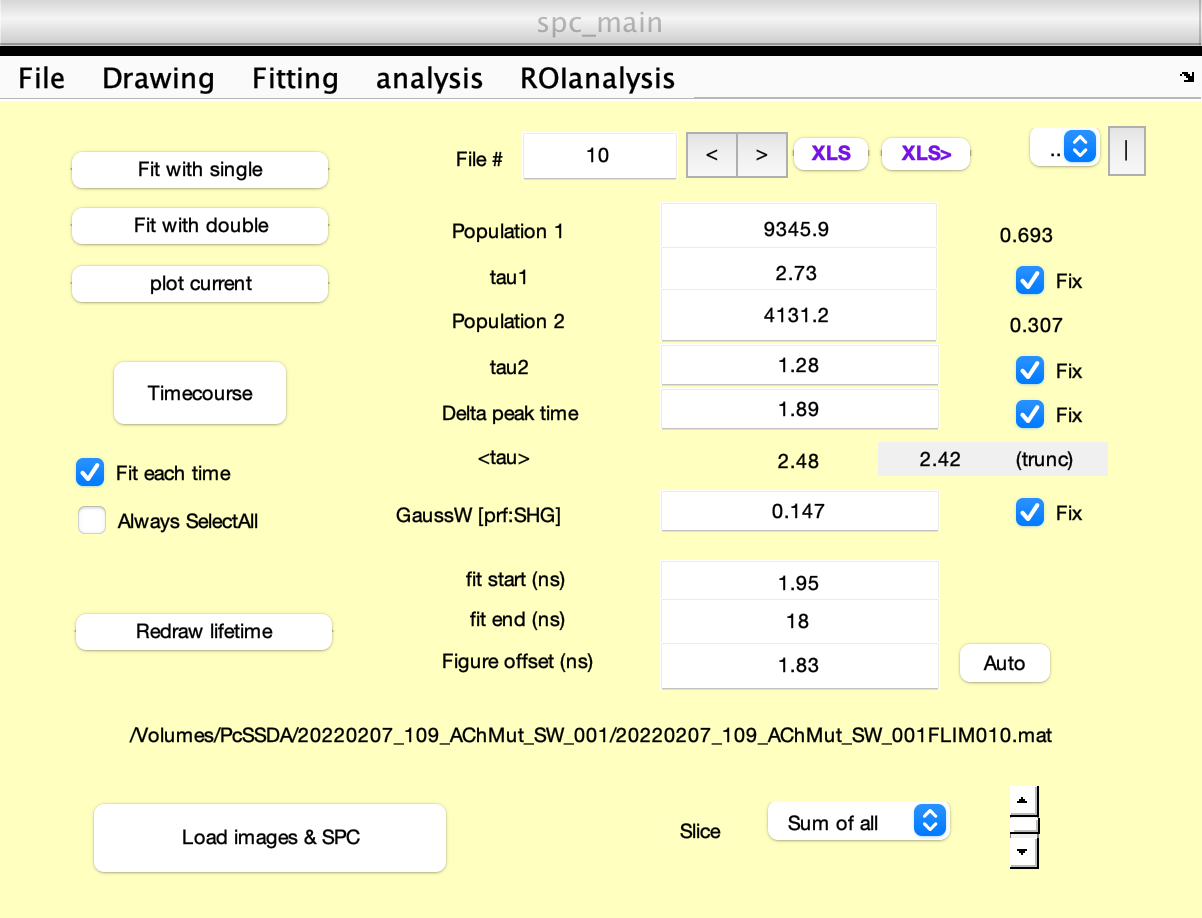

load('FLP_analysis.mat');

figure
plot(time_z_all_darkonly)

time_max = max(time_z_all_darkonly)

time_max =        35378


length(time_z_all_darkonly)

ans =        34329


min(time_z_all_darkonly)

ans =    0.792000000001281


time_pooled = (2:4:(ceil(time_max/4)*4)) + 12*900;
time_pooled = (0:1:(length(time_pooled)-1)) + 10800;
circadian_time = NaN(ceil(time_max/4),1);
% time_pooled = zeros(ceil(time_max/4),1);
tau_pooled = NaN(ceil(time_max/4),1);
states_pooled = NaN(ceil(time_max/4),1);

helper = 1;

for i = 1:ceil(time_max/4)
    index = find(time_z_all_darkonly > (i-1)*4 & time_z_all_darkonly <= i*4);
    circadian_time(i) = time_pooled(i);

    if isempty(index) == 0
        weighted_sum = sum(tau_empTrunc_all_darkonly(index).*intensity_all_darkonly (index));
        tau_pooled(i) = weighted_sum/sum(intensity_all_darkonly (index));
        states_pooled(i) = states_for_time_all_dark(index(1));
        helper = helper*0;
    elseif helper ==0
        tau_pooled(i) = tau_pooled(i-1);
        states_pooled(i) = states_pooled(i-1);
%         time_pooled(i) = NaN;

    end

end

size(tau_pooled)

ans =         8845           1


size(states_pooled)

ans =         8845           1


size(circadian_time)

ans =         8845           1


sum(isnan(tau_pooled))

ans =      0


sum(isnan(states_pooled))

ans =      0


sum(isnan(circadian_time))

ans =      0


NaN_index = isnan(tau_pooled);
tau_pooled(find(NaN_index == 1)) = [];
states_pooled(find(NaN_index == 1)) = [];
circadian_time(find(NaN_index == 1)) = [];
size(tau_pooled)

ans =         8845           1


size(states_pooled)

ans =         8845           1


size(circadian_time)

ans =         8845           1


states_pooled(find(states_pooled==2))=0;
states_pooled(find(states_pooled==3))=1;
states_pooled(find(states_pooled==4))=1;

Temperature_path='/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/'

Temperature_path = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/'

cd(Temperature_path)

rawData4 = ([Temperature_path,ExperimentName,'_0920.mat'])

rawData4 = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/20220207_109_AChMut_SW_001_0920.mat'

OptResults4=([Temperature_path,ExperimentName,'OptResults_0920.mat'])

OptResults4 = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/20220207_109_AChMut_SW_001OptResults_0920.mat'

save(rawData4, 'circadian_time','states_pooled','tau_pooled')

example2_Optimization(rawData4, 1, OptResults4)

iteration 1/121: PWP values of size and shift are [0.25 , -5.0].
iteration 2/121: PWP values of size and shift are [0.25 , -4.0].
iteration 3/121: PWP values of size and shift are [0.25 , -3.0].
iteration 4/121: PWP values of size and shift are [0.25 , -2.0].
iteration 5/121: PWP values of size and shift are [0.25 , -1.0].
iteration 6/121: PWP values of size and shift are [0.25 , 0.0].
iteration 7/121: PWP values of size and shift are [0.25 , 1.0].
iteration 8/121: PWP values of size and shift are [0.25 , 2.0].
iteration 9/121: PWP values of size and shift are [0.25 , 3.0].
iteration 10/121: PWP values of size and shift are [0.25 , 4.0].
iteration 11/121: PWP values of size and shift are [0.25 , 5.0].
iteration 12/121: PWP values of size and shift are [1.25 , -5.0].
iteration 13/121: PWP values of size and shift are [1.25 , -4.0].
iteration 14/121: PWP values of size and shift are [1.25 , -3.0].
iteration 15/121: PWP values of size and shift are [1.25 , -2.0].
iteration 16/121: PWP val

OptimizedParameters = struct with fields:
               sizePWP: 9.250000000000000
              shiftPWP: -4
        lowerAsymptote: 4.108976287114223
        upperAsymptote: 4.084819623682333
      wakeTimeConstant: 0.044143757312658
      nremTimeConstant: 0.050009903001094
              scalePWP: 0.013750760148329
    circadianAmplitude: 0.036845093311735
        circadianPhase: -1.308850577535366


correlation =    0.956478778331283


mean_error =    0.004748626727208


load(OptResults4)

figure
plot(simulatedT)
hold on
plot(rawT)

Temperature_path='/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/'

Temperature_path = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/'

cd(Temperature_path)


save([Temperature_path,'saved_rawDataName.mat'], ...
    'rawData1','OptResults1',...
    'rawData2','OptResults2',...
    'rawData3','OptResults3',...
    'rawData4','OptResults4')

Temperature_path='/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/'

Temperature_path = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/'

cd(Temperature_path)
load('saved_rawDataName.mat')

circadian_time_all = [];
tau_pooled_all = [];
states_pooled_all = [];

for i = 1:4
    eval(['load(rawData',num2str(i),')'])
    circadian_time_all = [circadian_time_all;circadian_time];
    tau_pooled_all = [tau_pooled_all;tau_pooled];
    states_pooled_all = [states_pooled_all;states_pooled];
end

circadian_time = circadian_time_all;
states_pooled = states_pooled_all;
tau_pooled = tau_pooled_all;


rawData_all = ([Temperature_path,'rawData_all_0920.mat'])

rawData_all = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/rawData_all_0920.mat'

OptResults_all =([Temperature_path,'OptResults_all_0920.mat'])

OptResults_all = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/OptResults_all_0920.mat'

save(rawData_all, 'circadian_time','states_pooled','tau_pooled')

example2_Optimization(rawData_all, 1, OptResults_all)

iteration 1/121: PWP values of size and shift are [0.25 , -5.0].
iteration 2/121: PWP values of size and shift are [0.25 , -4.0].
iteration 3/121: PWP values of size and shift are [0.25 , -3.0].
iteration 4/121: PWP values of size and shift are [0.25 , -2.0].
iteration 5/121: PWP values of size and shift are [0.25 , -1.0].
iteration 6/121: PWP values of size and shift are [0.25 , 0.0].
iteration 7/121: PWP values of size and shift are [0.25 , 1.0].
iteration 8/121: PWP values of size and shift are [0.25 , 2.0].
iteration 9/121: PWP values of size and shift are [0.25 , 3.0].
iteration 10/121: PWP values of size and shift are [0.25 , 4.0].
iteration 11/121: PWP values of size and shift are [0.25 , 5.0].
iteration 12/121: PWP values of size and shift are [1.25 , -5.0].
iteration 13/121: PWP values of size and shift are [1.25 , -4.0].
iteration 14/121: PWP values of size and shift are [1.25 , -3.0].
iteration 15/121: PWP values of size and shift are [1.25 , -2.0].
iteration 16/121: PWP val

OptimizedParameters = struct with fields:
               sizePWP: 1.250000000000000
              shiftPWP: -1
        lowerAsymptote: 2.154021653008678
        upperAsymptote: 4.195053206327412
      wakeTimeConstant: 31.374372997947152
      nremTimeConstant: 28.098013345678925
              scalePWP: -0.955552941259208
    circadianAmplitude: 0.708409278906265
        circadianPhase: -0.303139920120712


correlation =    0.740294627605548


mean_error =    0.012635065836284


load(OptResults_all)

figure
plot(simulatedT)
hold on
plot(rawT)

c = 

 Local Cluster

    Properties: 

                   Profile: local
                  Modified: false
                      Host: Pingchuans-iMac
                NumWorkers: 25
                NumThreads: 4

        JobStorageLocation: /Users/pingchuanma/Library/Application Support/MathWorks/MATLAB/local_cluster_jobs/R2021b
   RequiresOnlineLicensing: false

    

j1=batch(@example2_Optimization,0,{rawData1, 1, OptResults1})

j1 = 

 Job

    Properties: 

                   ID: 55
                 Type: independent
             Username: pingchuanma
                State: running
       SubmitDateTime: 21-Sep-2022 01:50:34
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 4

      AutoAttachFiles: true
  Auto Attached Files: 

j2=batch(@example2_Optimization,0,{rawData2, 1, OptResults2})

j2 = 

 Job

    Properties: 

                   ID: 56
                 Type: independent
             Username: pingchuanma
                State: running
       SubmitDateTime: 21-Sep-2022 01:50:38
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 4

      AutoAttachFiles: true
  Auto Attached Files: 

j3=batch(@example2_Optimization,0,{rawData3, 1, OptResults3})

j3 = 

 Job

    Properties: 

                   ID: 57
                 Type: independent
             Username: pingchuanma
                State: running
       SubmitDateTime: 21-Sep-2022 01:50:42
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 4

      AutoAttachFiles: true
  Auto Attached Files: 

j4=batch(@example2_Optimization,0,{rawData4, 1, OptResults4})

j4 = 

 Job

    Properties: 

                   ID: 58
                 Type: independent
             Username: pingchuanma
                State: running
       SubmitDateTime: 21-Sep-2022 01:50:48
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 4

      AutoAttachFiles: true
  Auto Attached Files: 

j5=batch(@example2_Optimization,0,{rawData_all, 1, OptResults_all})

j5 = 

 Job

    Properties: 

                   ID: 59
                 Type: independent
             Username: pingchuanma
                State: running
       SubmitDateTime: 21-Sep-2022 01:50:55
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 4

      AutoAttachFiles: true
  Auto Attached Files: 

load(OptResults_all)

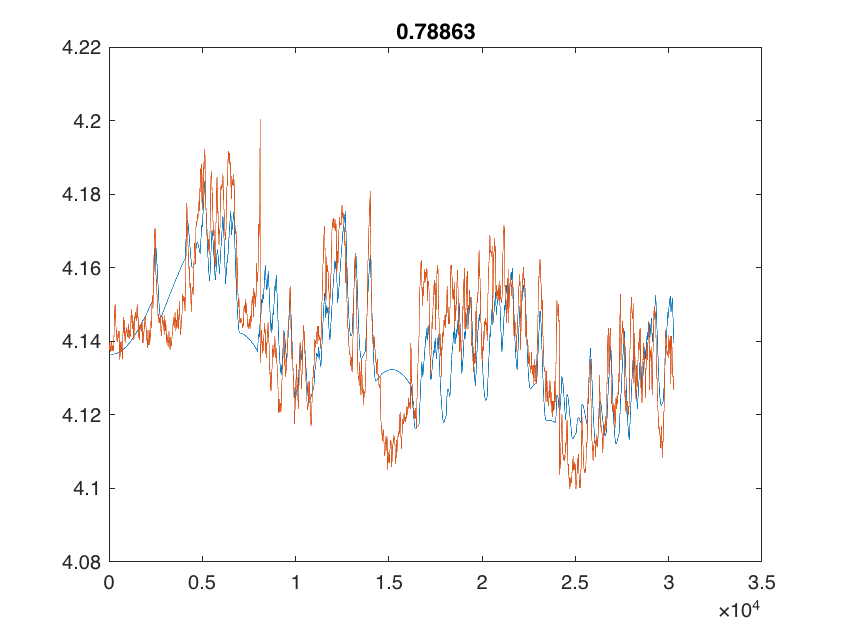

figure
plot(simulatedT)
hold on
plot(rawT)
title(num2str(correlation))

load(OptResults1)

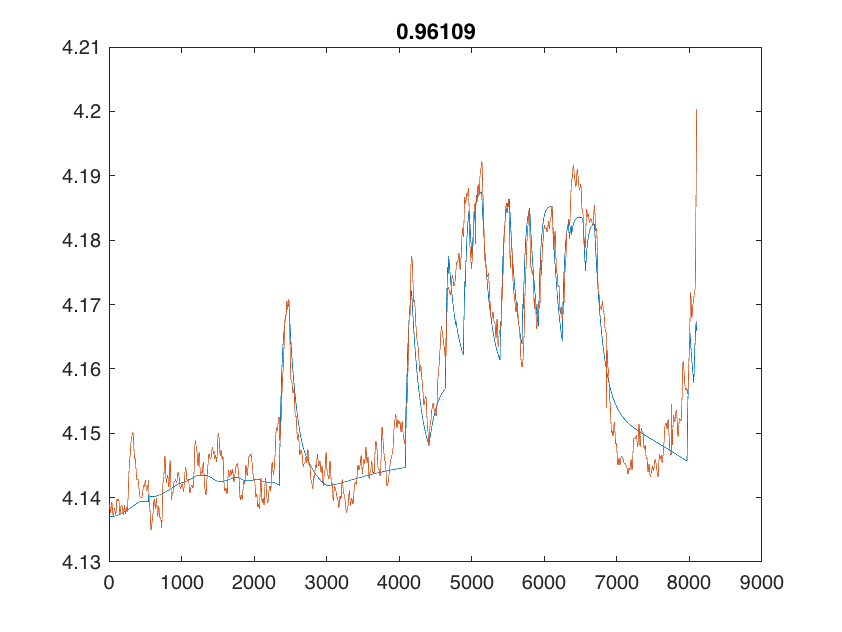

figure
plot(simulatedT)
hold on
plot(rawT)
title(num2str(correlation))

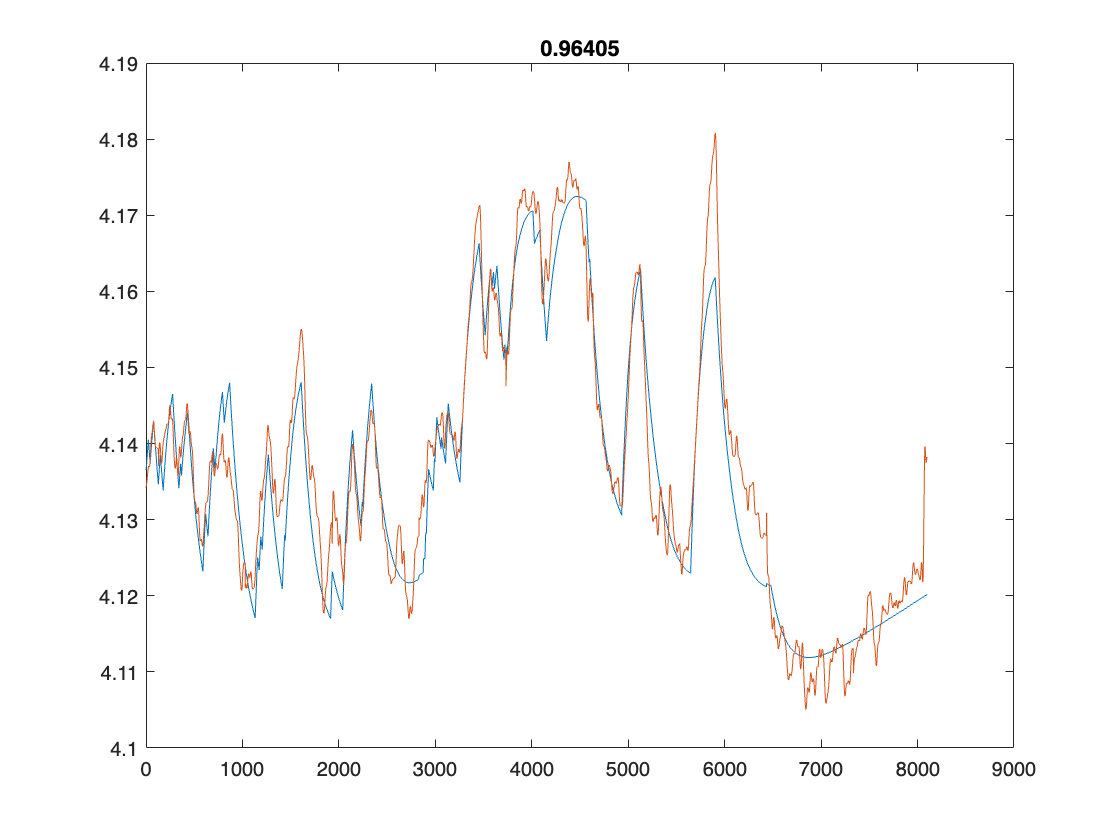

load(OptResults2)
figure
plot(simulatedT)
hold on
plot(rawT)
title(num2str(correlation))

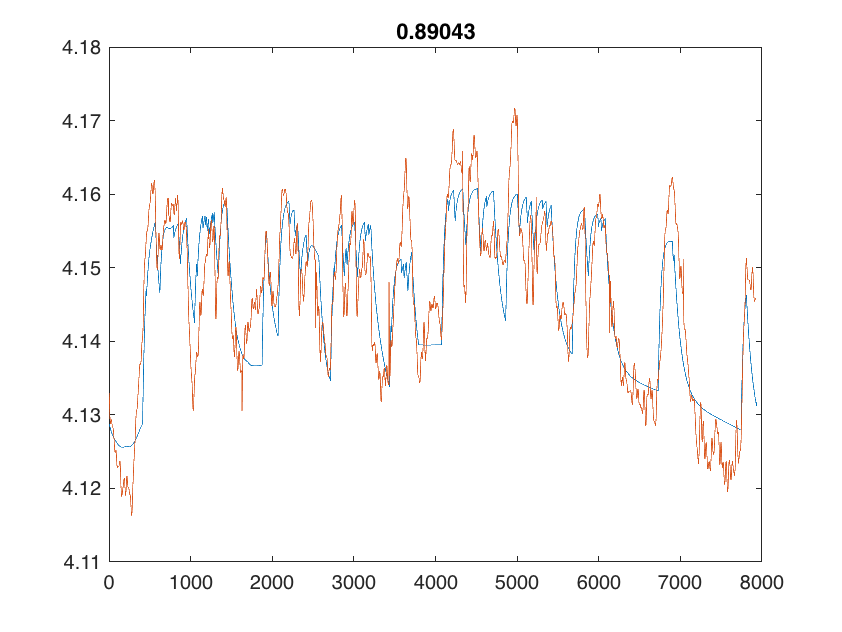

load(OptResults3)
figure
plot(simulatedT)
hold on
plot(rawT)
title(num2str(correlation))

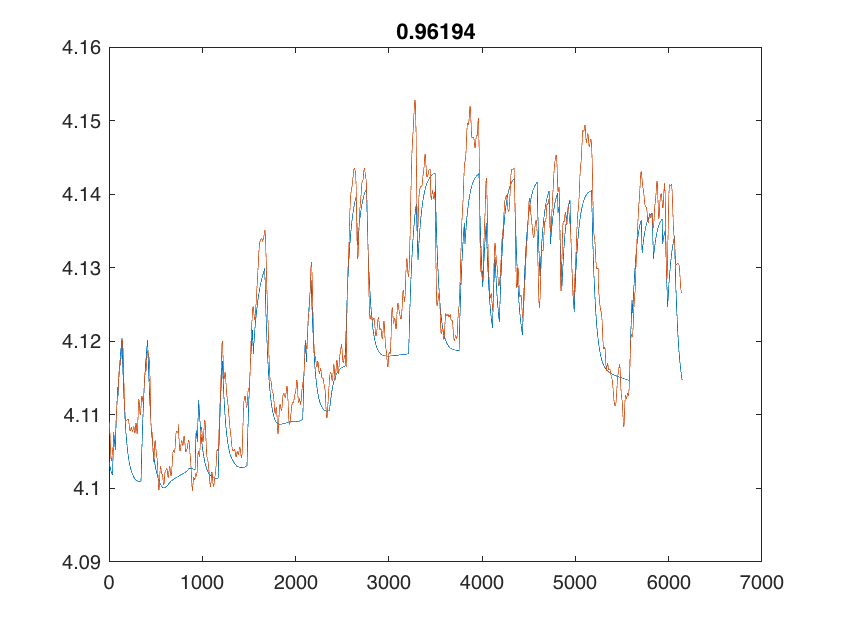

load(OptResults4)
figure
plot(simulatedT)
hold on
plot(rawT)
title(num2str(correlation))